clear all

% Params
fs = 8e3;

load('LP_opt8.mat')
[LP_B, LP_A] = sos2tf(SOS_LP_opt8, G_LP_opt8)

LP_B =     0.0076    0.0022    0.0160    0.0117    0.0117    0.0160    0.0022    0.0076


LP_A =     1.0000   -4.0731    8.5964  -11.3703   10.0829   -5.9468    2.1695   -0.3836


load('BP_opt6.mat')
[BP_B, BP_A] = sos2tf(SOS_BP_opt6, G_BP_opt6)

BP_B =     0.0503   -0.0000   -0.1344         0    0.1344    0.0000   -0.0503


BP_A =     1.0000   -0.0000    1.3799   -0.0000    1.1092   -0.0000    0.3599


%fvtool(BP_B,BP_A);
BP_B = [BP_B 0]

BP_B =     0.0503   -0.0000   -0.1344         0    0.1344    0.0000   -0.0503         0


BP_A = [BP_A 0]

BP_A =     1.0000   -0.0000    1.3799   -0.0000    1.1092   -0.0000    0.3599         0


%fvtool(BP_B,BP_A);
load('HP_opt8.mat')
[HP_B, HP_A] = sos2tf(SOS_HP_opt8, G_HP_opt8)

HP_B =     0.0933   -0.5022    1.2805   -1.9725    1.9725   -1.2805    0.5022   -0.0933


HP_A =     1.0000   -1.4437    2.5067   -1.4605    1.2557   -0.0592    0.1095    0.1384


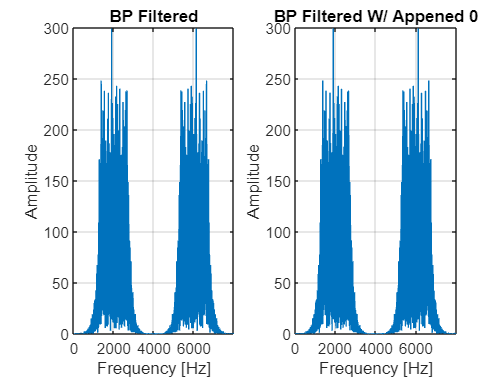


q_float = quantizer('single'); % Convert to signle precision
BP_A_q = quantize(q_float, BP_A);
BP_B_q = quantize(q_float, BP_B);

x = wgn(10000,1,0); % Gaussian noise (mean = 0, std = 1)
y_bp = filter(BP_B_q, BP_A_q, x);
y_bp2 = filter(BP_B_q, BP_A_q, x);

figure;
subplot(1,2,1);
plot(fs*[0:1/length(y_bp):(length(y_bp)-1)/length(y_bp)], abs(fft(y_bp)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('BP Filtered'); % Two-sided
grid on;

subplot(1,2,2);
plot(fs*[0:1/length(y_bp2):(length(y_bp2)-1)/length(y_bp2)], abs(fft(y_bp2)));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('BP Filtered W/ Appened 0'); % Two-sided
grid on;

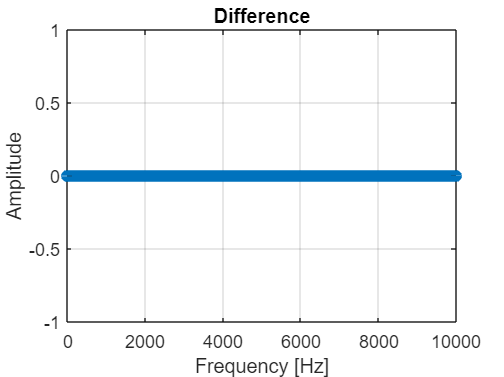


figure;
stem(abs(y_bp2-y_bp));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('Difference');
grid on;